# ECEN 5463 | EX 2

Collin Thornton

## Problem 1

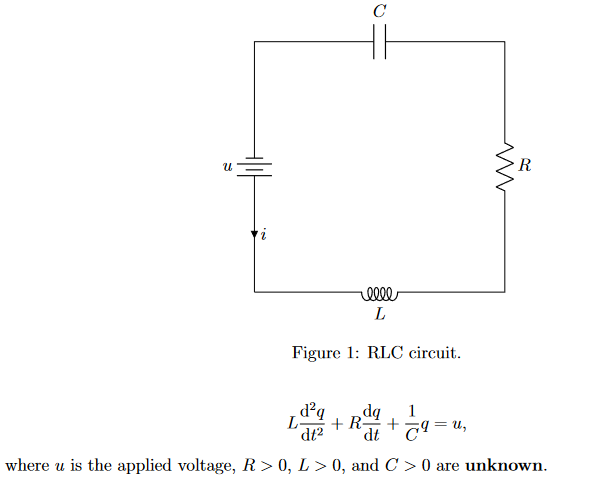

### 1.1 Design an implementable adaptive controller to drive the charge across the capacitor to 5 C. 

Closed Loop Dynamics:

$-L\ddot{e} -R\dot{e} +\frac{1}{C}\left(q_d -e\right)=u$, where $e=q_d -q$ and $q_d =5$

Let $r=\dot{e} +\alpha e$, $\theta =\left\lbrack \begin{array}{c}
\frac{1}{C}\\
R\\
L
\end{array}\right\rbrack$,  and $L\dot{r} =Y\left(e,r\right)\theta -u=L\ddot{e} +L\alpha \dot{e}$

Thus, $Y\left(e,r\right)=\left\lbrack \begin{array}{ccc}
q_d -q & -\dot{e}  & \alpha \dot{e} 
\end{array}\right\rbrack$.

Let $V\left(z\right)=\frac{1}{2}e^2 +\frac{L}{2}r^2 +\frac{1}{2}{\tilde{\theta} }^T \tilde{\theta}$, where $z=\left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta} 
\end{array}\right\rbrack$ and $\tilde{\theta} =\theta -\hat{\theta}$ and $\hat{\theta}$ is the estimate of $\theta$.


$$\dot{V} \left(z\right)=\frac{\partial V\left(z\right)}{\partial z}\dot{z} =\left\lbrack \begin{array}{ccc}
e & \mathrm{Lr} & {\tilde{\theta} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{e} \\
\dot{r} \\
\dot{\tilde{\theta} } 
\end{array}\right\rbrack =e\dot{e} +\mathrm{rL}\dot{r} +{\tilde{\theta} }^T \dot{\tilde{\theta} }$$



$$\dot{V} \left(z\right)=e\dot{e} +r\left(Y\left(e,r\right)\theta -u\right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$


We need to define $u$ and $\dot{\hat{\theta} }$ such that $\dot{V} \left(z\right)$is either negative definite or negative semidefinite.

Try $u=Y\left(e,r\right)\hat{\theta} +\frac{e^2 }{r}+r+\frac{e\dot{e} }{r}$ and $\dot{\hat{\theta} } ={\mathrm{rY}}^T \left(e,r\right)$


$$\dot{V} \left(z\right)=e\dot{e} +\mathrm{rY}\left(e,r\right)\left(\theta -\hat{\theta} \right)-e^2 -r^2 -e\dot{e} -{\tilde{\theta} }^T {\mathrm{rY}}^T \left(e,r\right)$$



$$\dot{V} \left(z\right)=-e^2 -r^2$$


$\dot{V} \left(z\right)\le 0$ on the line $z=\left\lbrack \begin{array}{c}
0\\
0\\
\tilde{\theta} 
\end{array}\right\rbrack$. Thus, $e=0$ is an equilibrium point for any $\tilde{\theta}$. As $D = \mathbb{R}^2$, the origin is GAS. Note that $\dot{q}$ and $\ddot{q}$ must settle to $0$ if $q$ settles to 0.

### 1.2 Simulate the controller to show that it works as expected. 

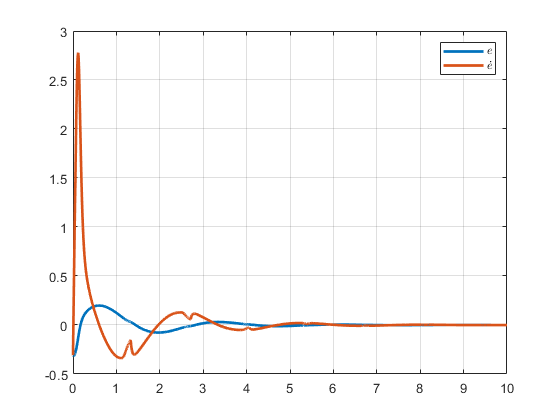

clear all;
close all;

p.C = rand;%1E-4*rand; % Pick a random C up to 100 uF
p.L = rand;%1E-3*rand; % Pick a random L up to 1 mF
p.R = rand;%1E5*rand;  % Pick a random R up to 100k
p.alpha = 5;     % alpha > 0
p.qd = 5;

% x0 = [q; dq]
x0 = (rand(2,1)-0.5);   % Pick a random starting charge & current
theta_hat_dot0 = [0;0;0]; % Start with zeros for estimate

y0 = [x0; theta_hat_dot0];

tspan = [0 10];
[t,y] = ode45(@(t,y) closedLoopDynamicsRLC(t,y,p), tspan, y0);

plot(t,y(:,1:2), "LineWidth", 2);
legend("$e$", "$\dot e$", "Interpreter", "latex");
grid on;

## Problem 2

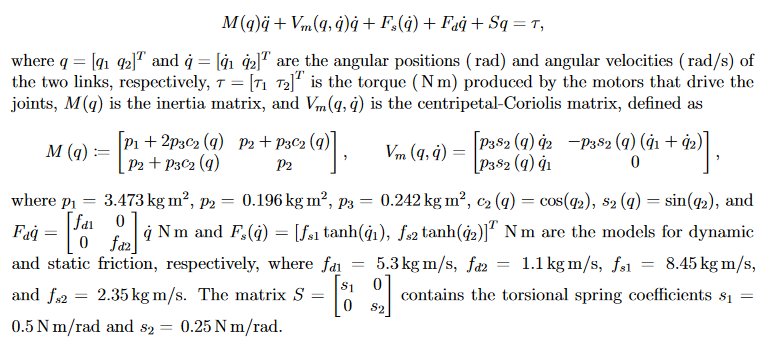

### 2.1 Assuming that the parameters are unkown, design a controller such that starting from any initial condition, the robot comes to rest at $q_d ={\left\lbrack \begin{array}{cc}
\pi  & \pi /2
\end{array}\right\rbrack }^T$

Closed loop dynamics: 

### 1.2 Simulate the controller to show that it works as expected. 

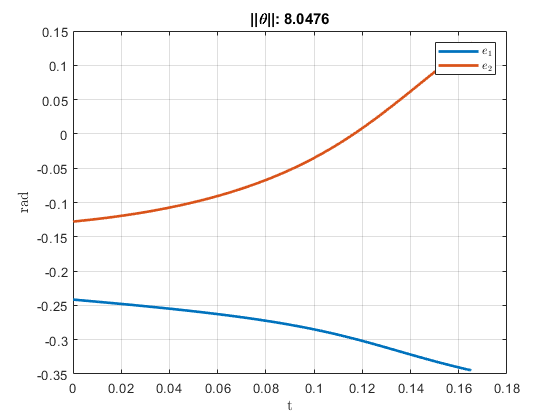

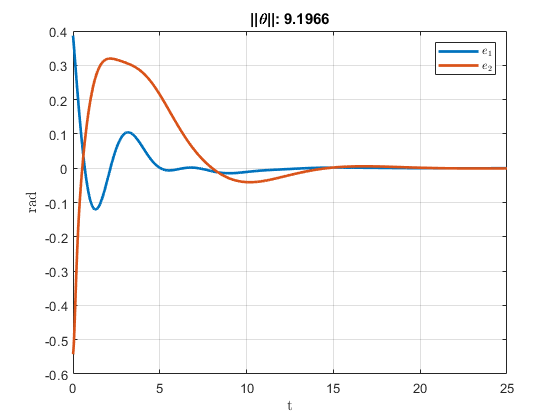

clear all;

for i = 1:2
    % Initialize theta to be a random value.
    p.theta = 5*rand(9,1);
    
    % Bias M to be in the neighborhood of the original problem definition.
    % This helps ode45 simulate the differential reliably, though the theory
    % shows convergence for all theta. 
    p.theta(2:3) = 0.5*(rand(2,1)+0.2);
    
    p.alpha = 1;     % alpha > 0
    
    
    p.qd = [pi; pi/2];
    
    % x0 = [q; dq]
    x0 = pi/2*(rand(4,1)-0.5);     % Pick a random starting positions and velocities
    
    % Random initial guess for theta_hat of same order as theta
    theta_hat_dot0 = 5*rand(9,1);
    theta_hat_dot0(2:3) = 0.5*(rand(2,1)+0.2);
    
    y0 = [x0; theta_hat_dot0];
    
    tspan = [0 25];
    [t,y] = ode45(@(t,y) closedLoopDynamicsDDR(t,y,p), tspan, y0);
    
    figure()
    plot(t,y(:,1:2), "LineWidth", 2);
    legend("$e_1$", "$e_2$", "Interpreter", "latex");
    xlabel("t", "Interpreter", "latex")
    ylabel("rad", "Interpreter", "latex")
    title("||\theta||: " + norm(p.theta))
    grid on;
end

function [dy] = closedLoopDynamicsRLC(t, x, p)
    p.Y = [p.qd, -x(2), p.alpha*x(2)];
    p.r = x(2) + p.alpha*x(1);
    
    dx = openLoopDynamicsRLC(t, x, controlRLC(t,x,p), p);
    theta_hat_dot = updateLawRLC(t, x, p);
    dy = [dx; theta_hat_dot];
end

function [u] = controlRLC(~, x, p)
    u = p.Y*x(3:5) + x(1)^2/p.r + p.r + x(1)*x(2)/p.r;
end

% x = [e; e_dot; theta_hat_dot], where e = qd - q
function [dx] = openLoopDynamicsRLC(~,x,u,p)
    dx(1,:) = x(2);
    dx(2,:) = (1/p.L)*((p.qd-x(1))/p.C - p.R*x(2) - u);
end

function theta_hat_dot = updateLawRLC(~, ~, p)
    theta_hat_dot = p.r*p.Y';
end

function [dy] = closedLoopDynamicsDDR(t, x, p)
    e  = x(1:2);
    de = x(3:4);
    
    a = p.alpha;
    r = de + a*e;
    p.r = r;
    
    q = p.qd-e;
    
    cq2 = cos(q(2));
    sq2 = sin(q(2));
    
    p.Y1 = [de(1)*a,  de(2)*a,  (de(1)*cq2+de(2)*cq2)*a,  -de(1),  0,  tanh(-de(1)),  0,     q(1),  0;
            0,   (de(1)+de(2))*a,  de(1)*cq2*a,            0,    -de(2),  0,     tanh(-de(2)), 0, q(2)];
    
    p.Y2 = zeros(2,9);
    p.Y2(:,1:3) = [ de(1)*a,  de(2)*a,  cq2*a*(2*de(1)+de(2));
                    0,  a*(1+de(2)),  de(1)*(sq2*(2*r(1)+r(2))+a*cq2+de(2)*sq2*r(1))];
    
    dx = openLoopDynamicsDDR(t, x, controlDDR(t, x, p), p);
    theta_hat_dot = updateLawDDR(t, x, p);
    dy = [dx;theta_hat_dot];
end

function [u] = controlDDR(~, x, p)
    e = x(1:2);
    de = x(3:4);
    r = p.r;
    
    u = (p.Y1 + p.Y2)*x(5:13) + [e(1)/r(1)*(e(1)+de(1)); e(2)/r(2)*(e(2)+de(2))] + r;
end

% x = [e; e_dot; theta_hat_dot], where e = qd - q
function [dx] = openLoopDynamicsDDR(~,x,u,p)
    p1  = p.theta(1);
    p2  = p.theta(2);
    p3  = p.theta(3);
    fd1 = p.theta(4);
    fd2 = p.theta(5);
    fs1 = p.theta(6);
    fs2 = p.theta(7);
    s1  = p.theta(8);
    s2  = p.theta(9);
    
    q = p.qd-x(1:2);
    dq = -x(3:4);
    
    M = [p1+2*p3*cos(q(2)),  p2+p3*cos(q(2));
         p2+p3*cos(q(2)),    p2];
    
    S = diag([s1, s2]);
    
    Fs = [fs1*tanh(dq(1)); fs2*tanh(dq(2))];
    
    Fd = diag([fd1, fd2]);
    
    sq2 = sin(q(2));
    Vm = [p3*sq2*dq(2),  -p3*sq2*(dq(1)+dq(2));
          p3*sq2*dq(1),  0];
    
    dx(1:2,:) = x(3:4);
    dx(3:4,:) = M\(Fs+S*q+Vm*dq+Fd*dq-u);
end

function theta_hat_dot = updateLawDDR(~, ~, p)
    theta_hat_dot = (p.Y1 + p.Y2)'*p.r;
end